# Experimental Fluids Lab #1

## Calibration

% Import Calibration Data (PC)
cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #1\';
LISTING = dir([cdir,'Calibration\test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Calibration\',filelead,'.mat'])
    setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
    cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
end

% % % Import Calibration Data (Mac OS)
% cdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #1/';
% LISTING = dir([cdir,'Calibration/test*.mat']);
% [~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
% LISTING=LISTING(idx);
% for hh =1:length(LISTING)
%     [~,filelead] = fileparts(LISTING(hh).name);
%     load([cdir,'Calibration/',filelead,'.mat'])
%     setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
%     cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
% end


% Conditions and Initialization

freq_f =  [0, 6, 10, 15, 20, 25, 30, 34, 37.5]; % fan frequency (Hz)
T_s = 10; % time (s)
freq_s = 20000; % Sample Frequency (Hz)
Cal_factor = 67.82; % Pressure Transducer Calibration: 67.82 [Pa/V]
Pvol_cal = abs(setra - setra(1)); % Zeroed Pressure transducer voltages for calibration (V)
P_Pitot = Cal_factor * Pvol_cal; % Pitot tube pressure readings (Pa)

P_amb1 = 1000.5 * 100; % Ambient pressure at the start of lab, convert from millibar -> Pa, (Pa)
P_amb2 = 1000.5 * 100; % Ambient pressure at the end of lab (same as start), convert from millibar -> Pa, (Pa)
T_amb1 = 23.8 + 273; % Ambient Temperature at start of lab, convert from centigrade -> Kelvin (K)
T_amb2 = 23.2 + 273; % Ambient Temperature at end of lab, convert from centigrade -> Kelvin (K)
R = 287; % Gas constant for air (J / Kg *K)

% Convert differntial pressure readings into velocities using Bernoulli's

rho1 = P_amb1 / (R * T_amb1); % Incompressible air density at start of lab (kg/m^)

for ii = 1:length(P_Pitot)

U_pitot(ii) = sqrt(2 * abs(P_Pitot(ii)) / rho1); % Air velocities from pitot tube measuremnt (m/s)

end

% Determine the total relative errors in velocity calibration from
% pressure/temperature sensors and pressure transducer

% Input and calculate device acccuracies and sources of uncertainty 

acc_P_amb = 4 * 100; % +/- Accuracy of ambient pressure measurement, converts from mBar to Pa (Pa)
acc_T_amb = 0.4; % +/- Accuracy of ambient temperature measurement (K)
acc_Tran = (0.5/100) * 550; % Accuracy of pressure transducer, converted from relative to Pa via Full-Scale (Pa)

res_P_amb = 1 * 100; % Resolution of ambient pressure measurement, converts from mBar to Pa (Pa)
res_T_amb = 0.1; % Resolution of ambient temperature measurement (K)

drift_T_amb = (T_amb1 - T_amb2) / 2; % drift error of initial and end ambient temperature (K)

% Calculate relative errors
rho_bar = ((P_amb1 / (R * T_amb1)) + (P_amb2 / (R * T_amb2))) / 2; % Mean of air density from start and end of lab (kg / m^3)

err_P_amb = sqrt(acc_P_amb^2 + res_P_amb^2); % Absolute error for ambient pressure measurement (Pa)
err_T_amb = sqrt(acc_T_amb^2 + res_T_amb^2 + drift_T_amb^2); % Absolute error for ambient temperature measurement (K)
err_Tran = acc_Tran; % Absolute error of pressure transducer, equal to its accuracy (Pa)
err_rho = sqrt((err_T_amb / (0.5 * (T_amb1 + T_amb2)))^2 + (err_P_amb / (0.5 * (P_amb1 + P_amb2)))^2); % Absolute error of air density, (Kg / m^3)

err_U_pitot = [];


% Calculate and display relative errors of each Pitot Velocity Measurement

for j = 1:length(U_pitot)

    err_U_pitot(j) = 100 * sqrt((0.5 * (err_Tran / P_Pitot(j)))^2 + (0.5 * (err_rho / rho_bar))^2);

end

% ****Insert Table figure here that dispalys each velocity and its error

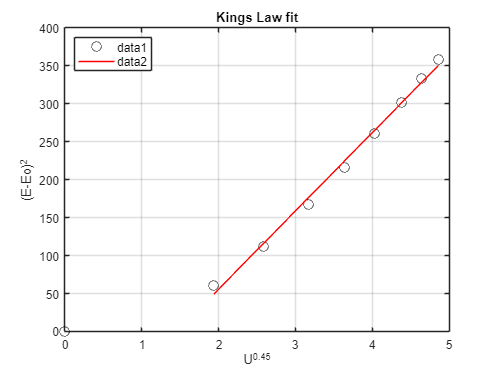

% Find the A and B constants in King's Law

Avol_cal = cta;
Y = [];
X = [];
n = 0.45;

for jj = 1:length(Avol_cal)

Y(jj) = (Avol_cal(jj) - Avol_cal(1))^2;
X(jj) = U_pitot(jj)^n;

end

y = Y(2:end); % Create data vectors excluding data first point
x = X(2:end);

p1 = polyfit(x, y, 1); % Use polyfit/val to fit the data with a 1st order polynomial
y_fit1 = polyval(p1, x);
y_cfit1 = polyval(p1, x);

figure % Create plot of the fitted data excluding first data point
plot(X,Y,'ko', MarkerSize=8)
hold on
plot(x, y_fit1, 'r-');
title('Kings Law fit')
xlabel('U^0.45')
ylabel('(E-Eo)^2')
legend('FontSize', 10, "Location","northwest");
grid("on")

hold off


A = p1(2) % A and B constants as found by polyfit of adjusted data sets

A = -150.5832

B = p1(1)

B = 103.1440

## Data Analysis

% Import Experimental Data

% Import Lab Data (PC)
cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #1\'; % change between OS's (no " or _ )';
LISTING = dir([cdir,'Boundary Layer\test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Boundary Layer\',filelead,'.mat'])
    E(:,hh)=timeseries_data(:,2)'; % anemometer voltages
end
y = readmatrix([cdir,'step_list']);y=y(:,4);


% % Import Lab Data (Mac OS)
% cdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #1/'; % change between OS's (no " or _ )';
% LISTING = dir([cdir,'Boundary Layer/test*.mat']);
% [~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
% LISTING=LISTING(idx);
% for hh =1:length(LISTING)
%     [~,filelead] = fileparts(LISTING(hh).name);
%     load([cdir,'Boundary Layer/',filelead,'.mat'])
%     E(:,hh)=timeseries_data(:,2)'; % anemometer voltages
% end
% y = readmatrix([cdir,'step_list']);y=y(:,4);

% Compute the discrete velocity profile of the Boundary Layer (Whole Data Set method)

% for i = 1:width(E)
%     for iii = 1:height(E)
% 
%     U_BL(iii,i) = ((((E(iii,i) - mean(Avol_cal(1,1)))^2 - A)) / B)^(1/n);
% 
%     end
% end

U_BL = (((E - Avol_cal(1,1)).^2 - A) ./ B).^(1/n); % Element wise King's Law

% Compute mean velocity profile of the Boundary Layer (Mean Voltage method)

% Leftover Code DO NOT USE

% for jjj = 1:width(E) % Mean of each of the 35 measurement samples
% 
%    E_mean(jjj) = mean(E(:,jjj));
% 
% end
% 
% for i = 1:width(E_mean) % Calculate mean velocities using King's law and averaged voltages
% 
%     U_BL_mean(i) = ((E_mean(i) - mean(Avol_cal(1,1))^2 - A) / B)^(1/n);
% 
% end


% Compute the Mean and standard deviation of the velocity profile

U_BL_mean = mean(U_BL);
U_BL_STD = std(U_BL);


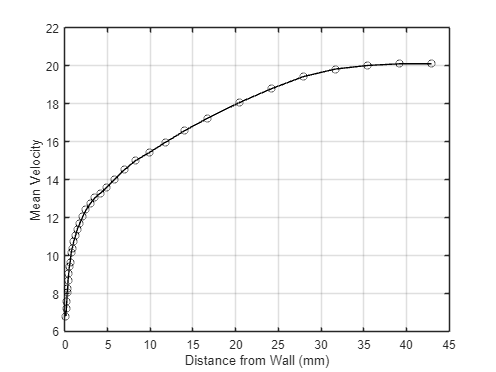

% Plot mean velocity profile (m/s) vs hot wire displacement (mm)
dist = [0.13 0.18 0.23 0.28 0.33 0.38 0.455 0.53 0.63 0.755 0.88 1.055 1.255 ...
    1.48 1.755 2.08 2.48 2.955 3.505 4.155 4.93 5.855 6.98 8.305 9.88 ...
    11.755 14.005 16.68 20.43 24.18 27.93 31.68 35.43 39.18 42.93]; % (mm)
figure
plot(dist, U_BL_mean, 'ko-')
ylabel('Mean Velocity')
xlabel('Distance from Wall (mm)')
grid("on")

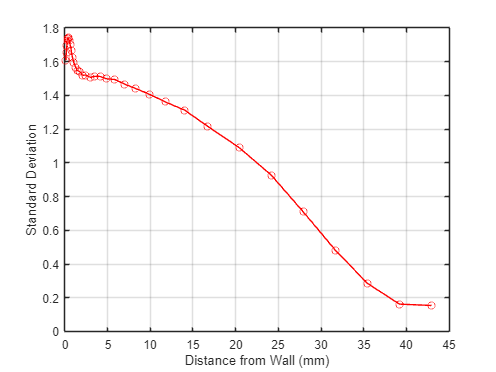



% Plot standard deviation (fluctuation) of the velocity profile

figure
plot(dist, U_BL_STD, 'ro-')
ylabel('Standard Deviation')
xlabel('Distance from Wall (mm)')
grid("on")

% Determine Boundary Layer Thickness (del) where velocity = 99% of the free stream

Free = (U_BL_mean(1,34) + U_BL_mean(1,35)) / 2; % Last two U mean points averaged to determine free stream (m/s)

U_BL_end = 0.99 * Free;

% 99% of the Free stream velocity = 19.91 m/s. Using the dist vs U_BL_mean
% graph, the BL thickness can be determined to be...

del = 33.2; %(mm)


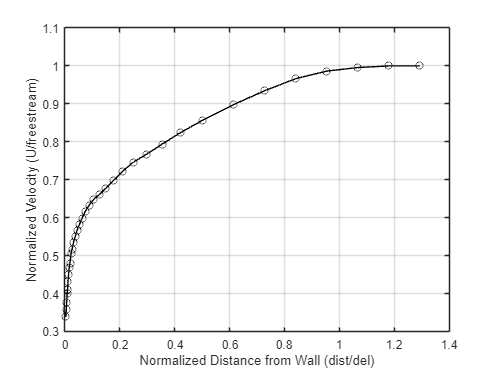

% Plot velocity and Fluctuation (STD) normalized by the free stream
% velocity (U_BL_mean) and the boundary layer thickness (del)

U_normal = U_BL_mean / Free;
dist_normal = dist / del;

figure
plot(dist_normal, U_normal, 'ko-')
ylabel('Normalized Velocity (U/freestream)')
xlabel('Normalized Distance from Wall (dist/del)')
grid("on")

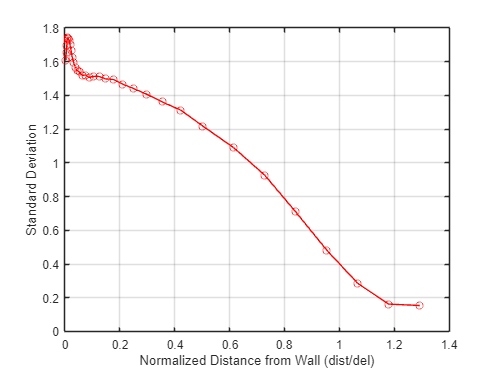


figure
plot(dist_normal, U_BL_STD, 'ro-')
ylabel('Standard Deviation')
xlabel('Normalized Distance from Wall (dist/del)')
grid("on")

% Determine the Friction Velocity (Utau) using the Clauser method

k  = 0.385; %Von Karman Constant
A = 4.17; 
Utau = 0.75 % Begin with Utau guess of 0.5

Utau = 0.7500

mu = 1.829e-05; % Dynamic viscosity for air at 296.6 K (Pa * s)
nu = 1.538e-05; % Kinematic viscosity for air at 296.6 K (m^2 /s)

U_plus = U_BL_mean / Utau;
Y_plus = (dist/1000) * (Utau / nu);



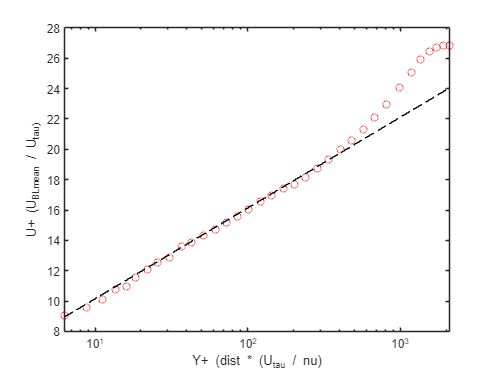

% Guess and check Utau values via the Clauser method

U_clauser = (1/k) * log(Y_plus) + A;

figure
semilogx(Y_plus,U_plus, 'ro')
hold on
semilogx(Y_plus,U_clauser, 'k--')

xlabel('Y+ (dist * (U_tau / nu)')
ylabel('U+ (U_BL_mean / U_tau)')

hold off

% Determine the local skin friction, Cf, using Sutherland's law

Cf_suth = 2 * (Utau / Free)^2

Cf_suth = 0.0028


% Determine local skin friction, Cf, using the Cole - Fernholz equation

Re_del = ((rho_bar * Free * (del / 1000)) / mu); % Reynolds number based on boundary layer thickness
Re_theta = 0.1 * Re_del; % Reynolds number based on... theta I guess

Cf_cole = 2 * ((1/0.384) * log(Re_theta) + 4.127)^-2 % Cole -Fernholz Equation, note 'log' is natural log

Cf_cole = 0.0030